Clustering test on data

First Technique : Random Cluster Start

Section one : Load data

clear all; close all;
rawData = load('Data.mat');
X = rawData.data.X;
Y = rawData.data.Y;
%randomize data set
Idx = randperm(length(X));
X = X(Idx,:,:);
Y = Y(Idx,:);

Section two visual data based on mean of first two dimensions

%Find the mean of first two color maps  
randomPortion =  randi(length(X)/3)

randomPortion = 1177

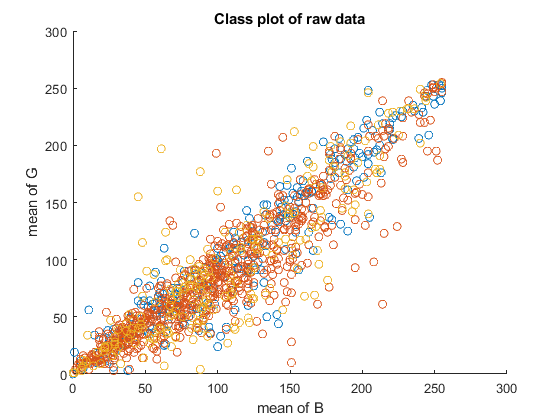

mean_X = mean(X(1:randomPortion,randomPortion,2),2);
mean_Y = mean(X(1:randomPortion,randomPortion,3),2);
%Plot means of each example in their class colour
figure();
hold on;
for class = 1:3
    plot(mean_X(Y(1:randomPortion)==class),mean_Y(Y(1:randomPortion)==class),'o','MarkerSize',6,'MarkerFaceColor','none')
end
title('Class plot of raw data')
ylabel('mean of G')
xlabel('mean of B')